# **Virtual Laboratory - Linear and Extended Kalman Filter Design for a Pendulum System**

**Overview**

The Kalman Filter virtual laboratory contains interactive exercises for students to study linear and extended Kalman filter design for state estimation of a simple pendulum system. Before completing the exercises in this lab, students are recommended to watch the first 5 videos of the [Understanding Kalman Filters tech talk series](https://www.mathworks.com/videos/series/understanding-kalman-filters.html). The videos will help students gain insights into why engineers use Kalman filters, how Kalman filter state estimation algorithm works and the different type of optimal state estimators. 

## Part 1: Simulate a simple pendulum and visualize its swing motion

In this part of the lab, you will simulate the motion of a simple pendulum in Simulink and use the simulation output to visualize pendulum's swing motion. [This Simulink model](matlab:open('/models/virtualPendulumModel.slx')) contains a simple pendulum modeled using [Simscape Multibody](https://www.mathworks.com/products/simscape-multibody.html) which lets you build a mechanical system using components such as bodies, joints, force elements, and sensors. Once you build the mechanical system, Simscape Multibody then solves the equations of motion and lets you simulate the system. On the left bottom corner of the pendulum block, you can click   to view the different mechanical components used to build the pendulum model: a fixed pivot connected with a link through a revolute joint. The pendulum takes two inputs, the driving torque $T$ and the process noise $w$ acting on the pendulum, and it outputs the angular position $\theta$. The pendulum model assumes no friction. This means when the pendulum is displaced by an angle $\theta$, it will swing back and forth at a constant amplitude.

**Task 1. **Open the virtual pendulum model: [virtualPendulumModel.slx](matlab:open('/models/virtualPendulumModel.slx')) and add blocks so that it matches the Simulink diagram below.

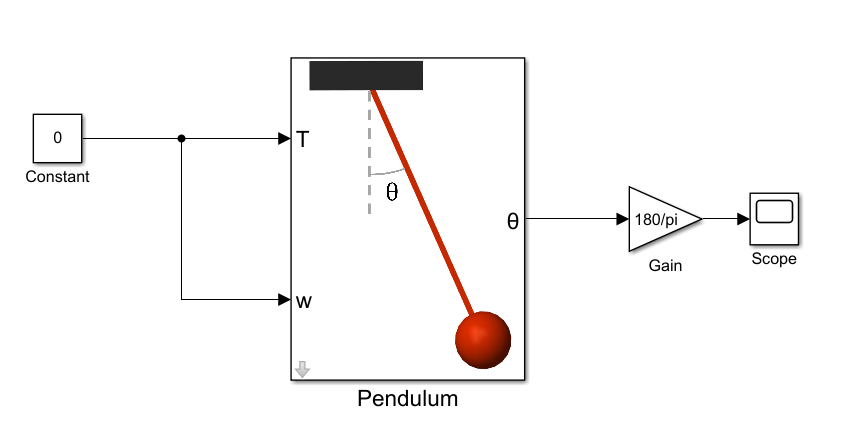

*Simulink model of a simple pendulum *

 **Pro-tip**: Double-click anywhere on the Simulink canvas and type the name of the block you want to add.

To create the model:

- Use a [Constant](https://www.mathworks.com/help/simulink/slref/constant.html) block to input 0 for both the input torque and process noise. In this example, there's no applied force at the pendulum tip. Instead the swing motion will be generated by displacing the pendulum by an initial non-zero angle. Initially, you'll assume there's no process noise acting on the system.

- Use a [Gain](https://www.mathworks.com/help/simulink/slref/gain.html) block to convert the unit of pendulum output (angular position $\theta$) from radians to degrees by setting the gain to 180/pi. Connect the output of the Gain block to a [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) to observe $\theta$. You will also visualize the pendulum response via an animation in the next section of this live script by setting Scope parameters for logging to workspace. To log $\theta \;\left(\textrm{degrees}\right)$to workspace, double-click the Scope block and navigate to **View > Configuration Properties > Logging.** Check "Log data to workspace", set the **Variable name **to **theta** and the **Save format** to **Structure**. Click **OK **to save the settings you've just set up. 

- Double-click the pendulum to open the block dialog which lets you specify the initial conditions. Confirm that the initial value of angular position is set to the parameter **theta0** and the initial value of angular velocity is set to **theta_dot0. **You will notice warnings   in the fields indicating that the parameter values are missing. You will specify the values for these parameters in the next step.

- To set the sample time, parameters and initial conditions of the pendulum, click the **Set parameters** button after uncommenting lines 5-6 in the code below and setting the initial value of $\theta$ (theta0) to pi/18 rad, and the initial value of $\dot{\theta}$ (theta_dot0) to 0. Completing this step properly will resolve the previous warnings.

 
m = 1;  % Pendulum mass [kg]
L = 0.5;    % Pendulum length [m]
g = 9.81;   % Gravity [m/s^2]
% theta0 =   
% theta_dot0 = 

- In the Simulink model, click  to run the simulation. Once the simulation starts, the Mechanics Explorer will open automatically and show a 3D animation during simulation. You can also open the scope to view the pendulum response. 

**Visualize the motion of the pendulum**

The below code lets you initialize the pendulum at different angles. It then simulates the model using [sim](https://www.mathworks.com/help/simulink/slref/sim.html) command and uses the logged simulation output to create an animation of pendulum's motion.

**Task 2. **Use the below slider (see line 7) to set the initial angle of the pendulum and click the checkbox to visualize the pendulum response. Wait until the animation runs to the end. You can then replay it by clicking   and choosing a slower or faster playback speed from the dropdown.

theta0 = deg2rad(0); % Initial value of theta [degrees]
visualize = false; % Click the checkbox to show the visualization
if(visualize)
    simTime = 3; % Simulation time in seconds
    simOut = sim("models/virtualPendulumModel", simTime); % simulates the pendulum model for a time span defied by "simTime" and saves simulation output to simOut
    animatePendulum(simOut.tout,simOut.theta.signals(1).values,[],[],rad2deg(theta0)) % Helper function that creates an animation using the simulation output from the model
end

**Sample Solution: **Check the below box to view pre-recorded video of a sample solution. The video shows an animation of the pendulum when the pendulum is initialized at 30 degrees.

viewSampleSolution = false;
if viewSampleSolution
    winopen("/animations/part1_task1.mp4");
end

Alternatively, you can open the video manually by first navigating to "**animations**" folder, and then right clicking on the "**part1_task1**" video and choosing "**Open outside of MATLAB**".

## Part 2: Compare measured to actual pendulum response 

The angular position of the pendulum can be measured using a sensor such as a rotary potentiometer. Such a measurement would be noisy and the measured value of the angular position would differ from its actual value. Complete the following task to learn how you can simulate a noisy sensor measurement of the pendulum's angular position and compare measured to actual pendulum response.

**Task 3.** Use the pendulum model that you've built in Part 1 of this lab and add blocks to the model so that it matches the Simulink diagram below.

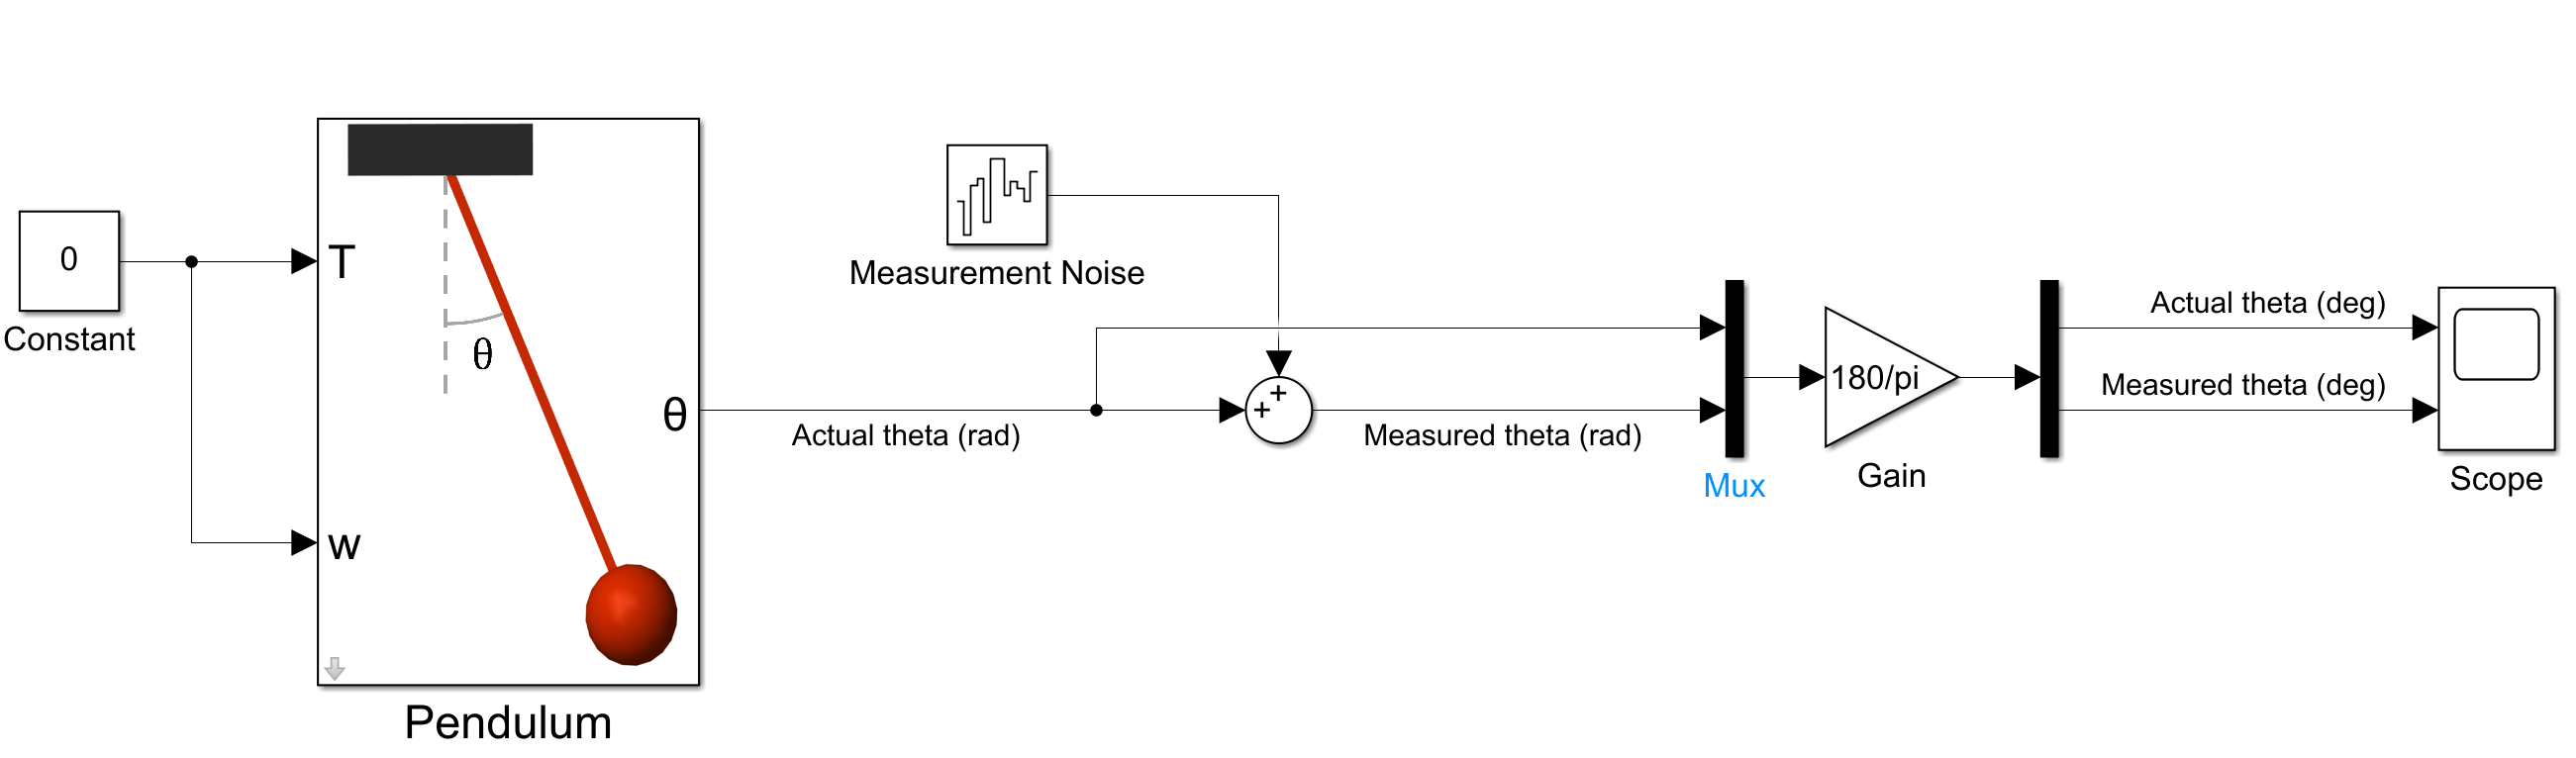

*Simulink model to simulate noisy measurement of the pendulum's angle*

To model and simulate the measured angular position:

- Add a [Band-Limited White Noise](https://www.mathworks.com/help/simulink/slref/bandlimitedwhitenoise.html) block to the model. Rename the block to **Measurement Noise** as seen in the above picture. Double-click the block and set the noise power to 0.000001 (1e-6) and sample time to 0.01 (1e-2).

- Use a [Sum](https://www.mathworks.com/help/simulink/slref/add.html) block to add measurement noise to the actual value of the angular position $\theta$. 

- Combine the actual and measured theta using a [Mux](https://www.mathworks.com/help/simulink/slref/mux.html) block and then use a Gain block to convert the unit from radians to degrees by choosing a gain of 180/pi. Use a [Demux](https://www.mathworks.com/help/simulink/slref/demux.html) block to extract the individual signals, connect them to the scope and label each signal accordingly.

**Task 4.** After completing the above steps, use the slider below to set pendulum's initial angle to a non-zero value and visualize the pendulum motion by clicking the checkbox. Once the animation runs to the end, you can replay it by clicking   and choosing a slower or faster playback speed from the dropdown.

theta0 = deg2rad(0); % Initial value of theta [degrees]
visualize = false; % Click the checkbox to show the visualization
if(visualize)
    simTime = 5; % Simulation time in seconds
    simOut = sim("models/virtualPendulumModel", simTime); % simulates the pendulum model for the time span defined by simTime and saves simulation output to simOut
    animatePendulum(simOut.tout,simOut.theta.signals(1).values,simOut.theta.signals(2).values,[],rad2deg(theta0)) % Helper function that creates an animation using the simulation output from the model
end

The animation shows the actual pendulum angle in green and the measured angle in red on the generated plots. How does actual pendulum response compare to measured response? What differences do you observe?

task4 = "<Replace this text with your answer but keep the quotes>"

## Part 3: Design a Kalman Filter to estimate the angular position of the pendulum

Kalman filter is an optimal state estimation algorithm that predicts the parameters of interest in the presence of measurement and process noise. In this part of the lab, you will implement a Kalman filter to filter out the noise from the pendulum's measured angular position.

In part 2, you learned that sensor measurements are subject to noise which leads to a measured response that differs from the actual system response. In addition to measurement noise, there's also process noise acting on the system due to change in the environmental conditions (e.g. effects of wind on the system response). Kalman filter uses a linear model of the system along with measurements to compute the optimal state estimates. The power of Kalman filter comes from its ability to produce more accurate state estimates than those that would be based on measurement or model prediction alone. To understand the working principle of Kalman filter algorithm and its equations, please check out [part 3](https://www.mathworks.com/videos/understanding-kalman-filters-part-3-optimal-state-estimator--1490710645421.html) and [part 4](https://www.mathworks.com/videos/understanding-kalman-filters-part-4-optimal-state-estimator-algorithm--1493129749201.html) videos in [this series](https://www.mathworks.com/videos/series/understanding-kalman-filters.html).

The Kalman filter computes the optimal state estimates of a linear plant model described by the state and measurement equations


$$\begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}+w\\
y=\textrm{Cx}+\textrm{Du}+v
\end{array}$$


where $w$ and $v$ represent the process and measurement noise, respectively. The random variables $w$ and $v$ are assumed to be independent, white and have normal distributions, $p\left(w\right)~N\left(0,Q\right)$ and $p\left(v\right)~N\left(0,R\right)$, where $Q$ and $R$ are process noise and measurement noise covariances, respectively. 

In this part of the lab, you will first linearize the nonlinear equation of motion of the pendulum and derive $A$, $B$, $C$ and $D$ matrices to create the state-space model required by the Kalman filter. You will then design a Kalman filter and perform experiments to understand the impact of process and measurement noise covariances as well as pendulum's and Kalman filter's initial conditions on the filter output.

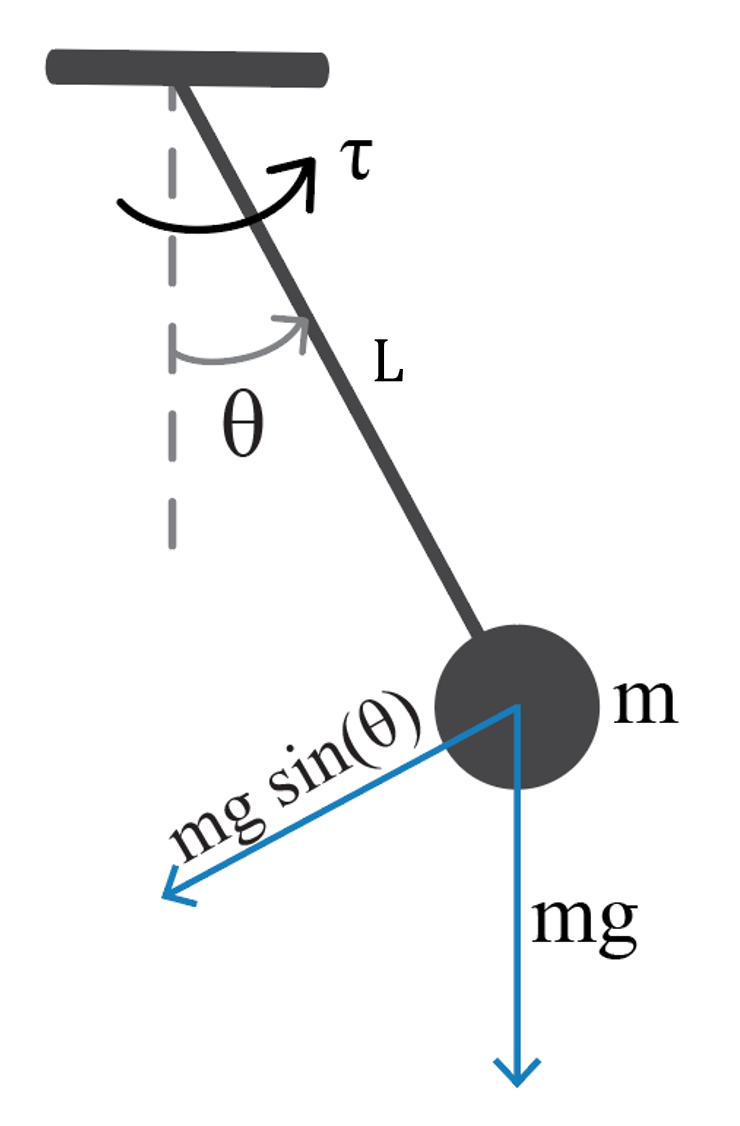

*Free body diagram of a simple pendulum*

The picture above shows the free-body diagram of the pendulum. The pendulum is initially at rest in a vertical position. When it's displaced by an angle $\theta$ and released, the force of gravity pulls it back towards its resting position. Its momentum causes it to overshoot and come to an angle $-\theta$ (assuming no frictional forces), and so on. The restoring force along the motion of the pendulum due to gravity is $-\textrm{mgsin}\left(\theta \right)$. Thus, according to Newton's second law, the equation of motion of the pendulum can be described by:


$$I\ddot{\theta} +\textrm{mgL}\;\sin \left(\theta \right)=\tau$$
    
$$\textrm{where}\;\;\;I=mL^2 \;\;\textrm{and}\;u=\tau$$
 

**Task 5. **Substitute $I$ into the above equation and rearrange the equation to bring it into the following form: 


$$\ddot{\theta} =\left(\textrm{Type}\;\textrm{rest}\;\textrm{of}\;\textrm{the}\;\textrm{rearranged}\;\textrm{equation}\;\textrm{here}\right)$$
 

Note that there is a nonlinear term associated with the angular position $\theta$. As shown in the below plot, the function of $\sin \left(\theta \right)$ acts linearly for small values of $\theta$. 

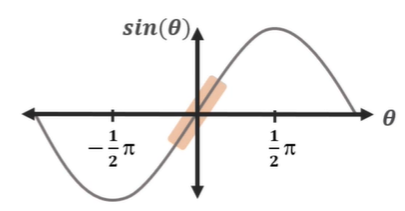

**Task 6. **Linearize the above equation using small angle approximation, $\sin \left(\theta \right)~\theta$, and rewrite the linearized equation below:


$$\ddot{\theta} =\left(\textrm{Type}\;\textrm{rest}\;\textrm{of}\;\textrm{the}\;\textrm{linearized}\;\textrm{equation}\;\textrm{here}\right)$$
 

**Task 7.** Use the linearized equation of motion to create the state-space model of the pendulum. A state-space model describes a system with a set of first-order differential equations using inputs $u$, outputs $y$, and state variables $x$, and can be written in the following form:


$$\begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
y=\textrm{Cx}+\textrm{Du}
\end{array}$$


To represent the pendulum model in state-space form, write two first-order differential equations for ${\dot{x} }_1$ and ${\dot{x} }_2$ by selecting the first state $x_1 =\theta$ and second state $x_2 =\dot{\theta}$ in the equation you found in task 4, and the measurement function $y$(note that the only measured state is $x_1$).Then, derive the state-space matrices $A$, $B$, $C$ and $D$.

% Uncomment the below code and define the state-space matrices A, B, C, D
% A = 
% B = 
% C =
% D =

Run the code you wrote above by clicking on the left side (   ) of this section. 

**Task 8.** Use the virtual pendulum model from Part 2 and add blocks to the model so that it matches the Simulink diagram below.

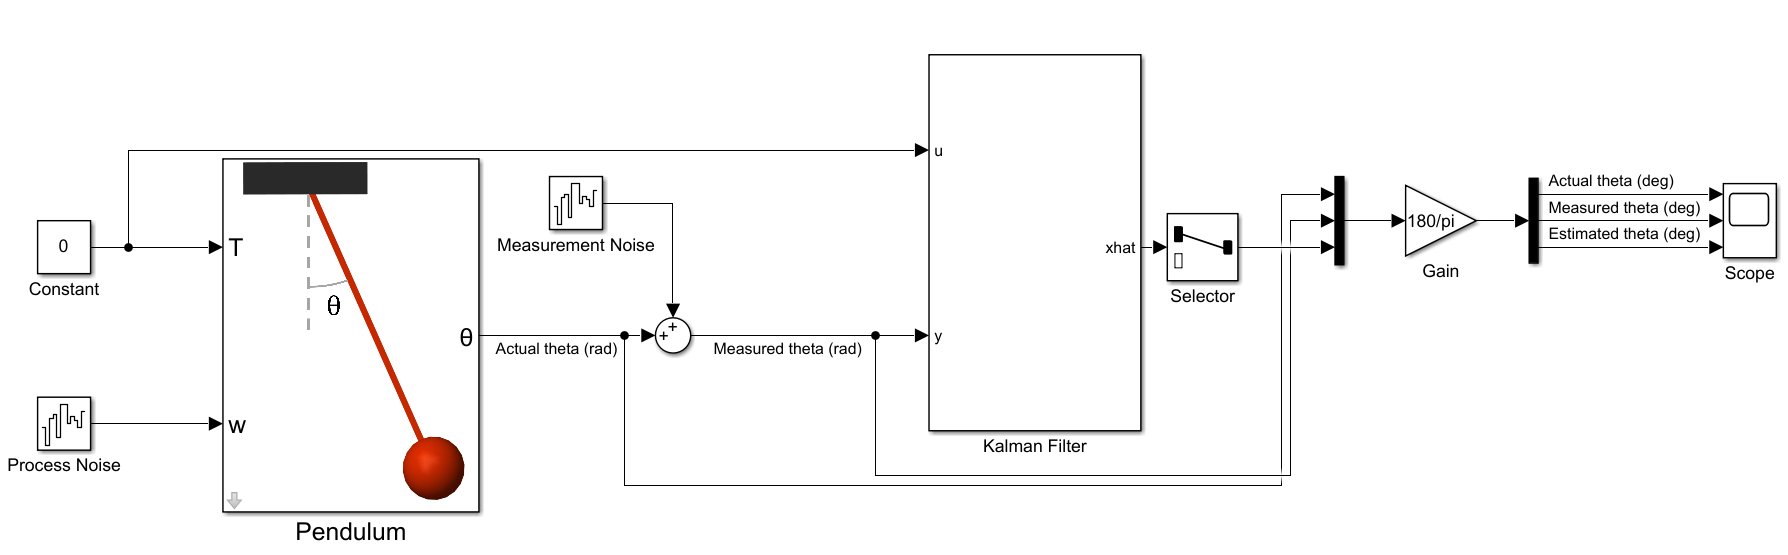

*Simulink model to estimate pendulum's angular position using a linear Kalman filter*

To implement the Kalman filter and create the model seen above, complete the following steps:

- Add process noise to the pendulum model by using a [Band-Limited White Noise](https://www.mathworks.com/help/simulink/slref/bandlimitedwhitenoise.html) block. Rename the block to **Process Noise** as shown in the above picture. Set the noise power and sample time to 0.00001 (1e-5) and 0.01 (1e-2), respectively.

- Add a [Kalman Filter](https://www.mathworks.com/help/control/ref/kalmanfilter.html) block which takes known inputs $u$ and measurements $y$ and computes the state estimates $\textrm{xhat}$. Connect the input torque $T$ to input port $u$, and measured angular position $\theta$ to input port $y$. States estimates computed by the Kalman filter is a 2x1 vector containing estimates of $\theta$ and $\dot{\theta}$.  Use a [Selector](https://www.mathworks.com/help/simulink/slref/selector.html) block to select only the estimated $\theta$ and feed it along with actual and measured theta to the mux block. Update the demux block to output three signals and connect the estimated theta to the scope and label it as seen in the above picture.

Next, double-click the Kalman Filter to open up the block dialog and specify the filter settings as described below:

- Kalman Filter block estimates discrete-time states by default. Change time domain setting to "Continuous-Time" for estimating continuous-time states. Under **Model Parameters > System Model**, select **Individual A, B, C D matrices **as for the model source abd enter state space matrice variables that you previously defined in Task 5.

- Click the below button to reset the initial conditions of the pendulum model to the values shown in the code below. Then, set the **initial states** of the **Kalman filter block** to be the same as the initial conditions of the pendulum: [pi/18 0].

 
theta0 = pi/18;
theta_dot0 = 0;

- The process noise covariance $Q$ is a 2x2 diagonal matrix with the diagonal elements corresponding to the expected variance in the states. In the pendulum system, the process noise acts only on the angular acceleration, so set $Q$ to $\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\ldotp 001
\end{array}\right\rbrack$by typing diag([0, 1e-3]) in **Noise Characteristics > Q**. And set the measurement noise covariance $R$ to 1e-4. Assume there's no correlation between $Q$ and $R$, so $N$ is 0.  Click **OK **to apply the changes.

**Task 9.** Run this section to compare actual pendulum response to measured and estimates responses. Use the drop-down to select different pair of signals for comparison.

simOut = sim("models/virtualPendulumModel", 5); % Simulates the model for 5 seconds and saves simulation output to simOut
animatePendulum(simOut.tout,simOut.theta.signals(1).values,[],simOut.theta.signals(3).values,rad2deg(theta0));

**Task 10.** Comment on the performance of the Kalman filter. Does the Kalman filter you designed above provide a good estimate for the pendulum's angular position?

task10 = "<Replace this text with your answer but keep the quotes>"

**Task 11.** In the Kalman filter block, change the value for the initial estimate of theta to pi/16, simulate the system by pressing  in the Simulink model and open scope to view simulation results. Note that to view signal labels, you can enable scope legends by selecting **View > Legend**. Repeat the simulation after setting initial estimate of theta to pi/14. 

What changes do you observe in the estimated theta when Kalman filter's initial conditions are different than the pendulum model? Approximately how long does it take the filter to converge?

task11 = "<Replace this text with your answer but keep the quotes>"

**!** Once you're done with this task, set the **initial theta back to pi/18 in the Kalman filter block** before moving on to the next exercise.

When designing the Kalman filter, we assumed the process noise and measurement noise covariances $Q$ and $R$ were known. The band-limited white noise block approximates the covariance of white noise as the noise power divided by the sample time. The noise powers used in the process and measurement noise blocks were respectively 1e-5 and 1e-6, which corresponds to $Q$ = 1e-3 (1e-5/1e-2) and $R$ = 1e-4 (1e-6/1e-2). We used the same $Q$ and $R$ in the design of the Kalman filter. If prior knowledge of $R$ is not available, it can be estimated using sensor measurements as $R$ represents the noise characteristics of the sensor. 

**Task 12.** To estimate the measurement noise covariance R, take measurements while the pendulum rests still at 0 degree and compute the variance of the measured output. Validate that the computed variance is close to previously set value of $R$, 1e-3. You can use [sim](https://www.mathworks.com/help/simulink/slref/sim.html) command to simulate your model.  

% Write your code here

In task 13 and 14, you will demonstrate the effect of $R$ and $Q$ on the Kalman filter output. Before you do so, set the process and measurement noise covariances in the **Kalman filtern block** to parameters **Q** and **R**, respectively. You will change the values of these parameters in the given code in the following sections.

**Task 13.** Demonstrate the effect of $R$ on the Kalman filter output. Assume that you don't have an estimate of the measurement noise. Use the below drop-down to set $R$ to different values. What behavior do you observe in the Kalman filter output as you decrease $R$ and comment on whether the filter relies more on the measurements or the model and why? Go to this section to type your response.

theta0 = pi/18;
Q = diag([0 1e-3]);
R = 1e-4;
simOut = sim("models/virtualPendulumModel", 5);
figure;
hold on;
plot(simOut.tout,simOut.theta.signals(2).values,'r')
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 2)
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 1)
legend("Measured response","Actual response","Kalman filter estimate")

task13 = "<Replace this text with your answer but keep the quotes>"

**Task 14.** Demonstrate the effect of $Q$ on the Kalman filter output. Assume that you don't have a good estimate of the process noise. Use the below drop-down to set $Q$ to different values. What behavior do you observe in the Kalman filter output as you increase $Q$ and comment on whether the filter relies more on the measurements or the model and why? Go to this section to type your response.

theta0 = pi/18;
R = 1e-4;
Q = diag([0 0.001]);
simOut = sim("models/virtualPendulumModel", 5);
figure;
hold on;
plot(simOut.tout,simOut.theta.signals(2).values,'r');
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 2)
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 1);
legend("Measured response","Actual response","Kalman filter estimate");

task14 = "<Replace this text with your answer but keep the quotes>"

**Task 15. **In task 11, you initialized the pendulum model and Kalman filter at different values and tested filter's response for the different initial conditions. This time, you will use the same initial conditions in the model and filter but start the pendulum at a significantly larger angle to test filter's performance. Open Kalman filter block and set the **initial states** to **[theta0 0]**. Using the slider below, increase the pendulum's initial angle to larger values and comment on how this impacts the Kalman filter estimate. The code given in this section lets you compare the responses of the linear and nonlinear pendulum models for different conditions. Use this comparison to explain why Kalman filter cannot provide a good estimate for larger values of theta0. Finally, go to this section to type your response.

theta0 = 15;
theta0 = deg2rad(theta0);
Q = diag([0 1e-3]);
R = 1e-4;
simOut = sim("models/virtualPendulumModel", [0 10]);
figure;
hold on;
plot(simOut.tout,simOut.theta.signals(2).values,'r');
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 2)
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 1);
legend("Measured response","Actual response","Kalman filter estimate");

task15 = "<Replace this text with your answer but keep the quotes>"

The following code lets you compare the responses of the linear and nonlinear pendulum models for different initial angles. 

theta0 = 5;
theta0 = deg2rad(theta0);
sys = ss(A,B,C,D);
load_system('models/virtualPendulumModel.slx')
set_param('virtualPendulumModel/Process Noise','Cov','0')
tfinal = 10;
[y,t] = initial(sys,[theta0;0], tfinal);
simOut = sim("models/virtualPendulumModel", tfinal);
figure;
plot(simOut.tout,simOut.theta.signals(1).values,'b');
hold on;
plot(t,rad2deg(y))
legend('Nonlinear pendulum model','Linear pendulum model')
set_param('virtualPendulumModel/Process Noise','Cov','1e-5')

## Part 4: Design an Extended Kalman Filter to estimate the angular position of the nonlinear pendulum system

After completing the previous exercise, you will observe that the Kalman filter cannot provide a good estimate when the system being estimated is nonlinear. To deal with the nonlinear system, you will implement an extended Kalman filter which is a variation of the Kalman filter and works by linearizing the nonlinear system model around the current state estimate. You can watch [this video](https://www.mathworks.com/videos/understanding-kalman-filters-part-5-nonlinear-state-estimators-1495052905460.html) to learn the different types of nonlinear state estimators and how they work. In this part of the lab, you will implement an extended Kalman filter to estimate the pendulum's angle and compare the estimation results of the linear and extended Kalman filters. 

**Task 16.** Use the virtual pendulum model from Part 3 and add blocks to the model so that it matches the Simulink diagram below.

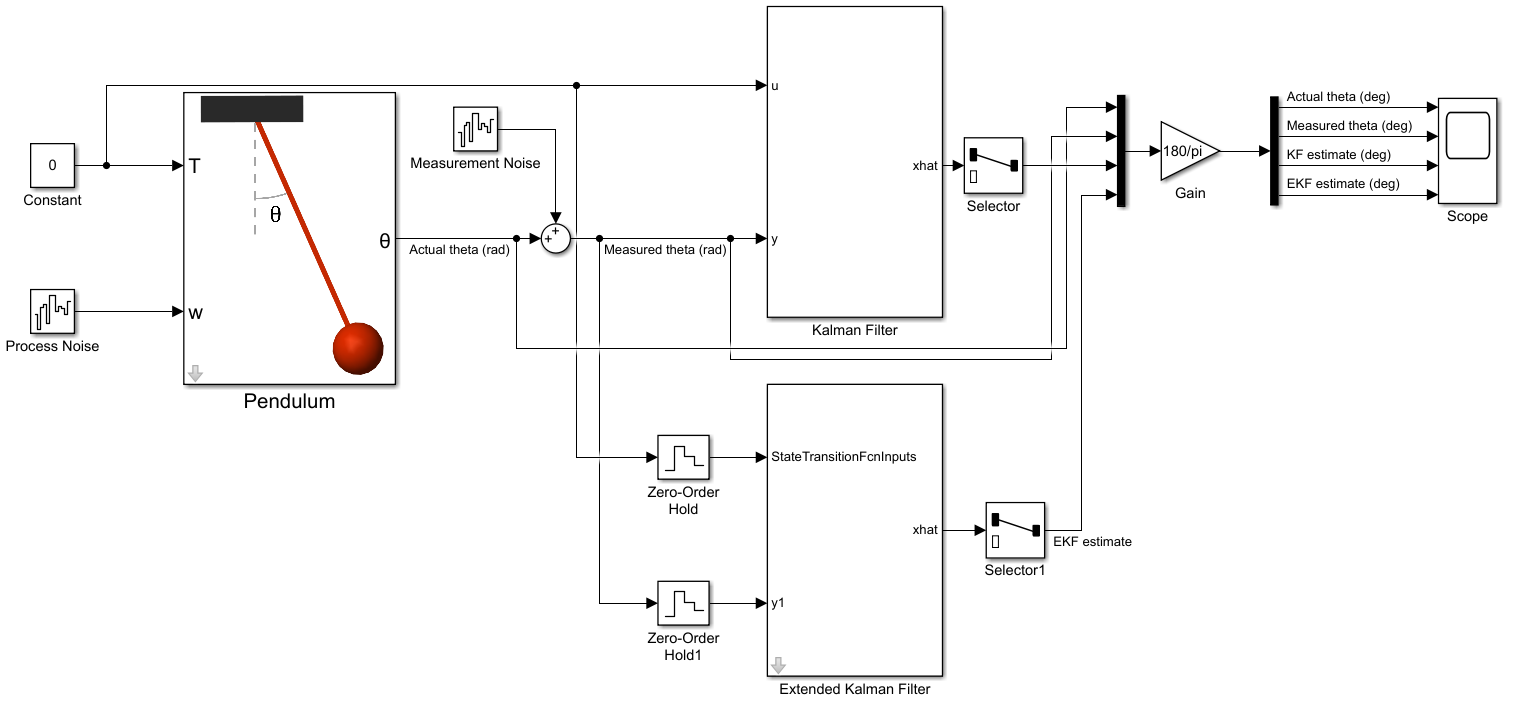

*Simulink model to compare state estimation of a nonlinear model using linear and extended Kalman filters*

To implement an extended Kalman filter and compare it to the previously designed Kalman filter, complete the following steps:

- Add an Extended Kalman Filter block to the model. Use the same inputs you used for the linear Kalman filter and connect T and measured theta to **StateTransitionFcnInputs** and **y1** inports of the Extended Kalman Filter, respectively. 

- Extended Kalman Filter block computes estimates of a discrete nonlinear system. So, you need to use the [Zero-Order Hold](https://www.mathworks.com/help/simulink/slref/zeroorderhold.html) block to descretize the input torque and the measured theta. In the zero-order hold block, enter a sample time of 0.01. Use a [Selector](https://www.mathworks.com/help/simulink/slref/selector.html) block to connect theta estimated by the Extended Kalman Filter (first element of xhat) to the mux block and configure demux block to output all fours signals. Label the signals as seen in the above picture. 

**Task 17. **Double-click the Extended Kalman Filter to view the required functions and parameters you need to specify for designing the filter. As seen under the **System Model** tab in the block dialog, the Extended Kalman filter requires a discrete-time state transition function that describes the evolution of system states from one time step to the next. The filter also needs a measurement function that describes how the states are related to measurements. Next, you will create these functions and specify them in the block dialog along with other required parameters such as covariances.

**State Transition Function**

To compute the discrete-time state transition function, you need to first discretize the continuous-time state equations of the nonlinear pendulum model that are given below.  


$$\begin{array}{l}
{\dot{x} }_1 =x_2 \\
{\dot{x} }_2 =-\frac{g}{L}\sin \left(x_1 \right)+\frac{u}{{\textrm{mL}}^2 }
\end{array}$$


where $x_1 =\theta$ and $x_2 =\dot{\theta}$.

Compute the discrete-time state equations by discretizing the above state equations using Euler discretization which approximates the derivative operator as $\dot{x} \approx \frac{x_{n+1} -x_n }{T_s }$ ($T_s$ is the discrete sampling period). Write the discrete-time state equations in the following form:


$$\begin{array}{l}
x_1 \left\lbrack k+1\right\rbrack =x_1 \left\lbrack k\right\rbrack +x_2 \left\lbrack k\right\rbrack T_s \\
x_2 \left\lbrack k+1\right\rbrack =x_2 \left\lbrack k\right\rbrack -\left(\frac{g}{L}\sin \left(x_1 \left\lbrack k\right\rbrack \right)+\frac{u}{mL^2 }\right)T_s 
\end{array}$$


**Task 18.** [myStateTransitionFcn](matlab:open('/myStateTransitionFcn.m')) is the state transition function that is used by the Extended Kalman Filter. Open [myStateTransitionFcn](matlab:open('/myStateTransitionFcn.m')) and complete it by writing code to define the discrete-time state equations you've found above. The state transition function you've just created is specified under **System Model >** **State Transition > Function** in the Extended Kalman Filter block dialog. You can provide an analytical Jacobian for the state transition function. If an analytical Jacobian is not provided, the extended Kalman filter algorithm computes the Jacobian numerically. You can use the default setting for the process noise as the pendulum model has an additive process noise. Set the process noise covariance to diag([0 1e-3]), and the initial states to [pi/2 0]. Set the initial covariance for the state estimation error to a small value such as 1e-3. Note that if you don't have confidence in the initial state values, you need to specify a high value for the initial covariance.

**Task 19. ****Measurement Function****: **The filter also needs a measurement function that describes how the states are related to measurements. The continuous-time measurement function of the pendulum model is given below.


$$y=x_1$$


[myMeasurementFcn](matlab:open('/myMeasurementFcn.m')) is the measurement function that is used by the Extended Kalman Filter. Open [myMeasurementFcn](matlab:open('/myMeasurementFcn.m')) and complete it by writing code to define the measurement equation given above. The measurement function is specified under **System Model > State Transition > Measurement** **1 **in the Extended Kalman Filter block dialog. You can provide an analytical Jacobian of the state transition function for the state transition function. If an analytical Jacobian is not provided, the extended Kalman filter algorithm computes the Jacobian numerically. You can use the default setting for the measurement noise which is set to additive noise. Set the measurement noise covariance to 1e-4, and specify a sample time of 0.01 under Settings > Sample time and click OK.

**Task 20. **Once you're done with the design of the extended Kalman filter, run the Simulink model and open the scope to view the simulation results. Are you able to get a good estimate with the extended Kalman filter? How does the extended Kalman filter estimate compare to the estimate computed by the linear Kalman filter?

task20 = "<Replace this text with your answer but keep the quotes>"

*Copyright 2021 The MathWorks, Inc.*